# Characterize Motor Parameters (Inertia) using Curve Fitting

## Open Test Bench and Run Coast Down Test

#### Open Test Bench and Setup Coast Down Experiment

mdl = 'FieldOrientedController_RCP';
open_system(mdl);
switchConfig('RCP');
switchMotorKit('SG_Inverter_RCP_Kit');

#### Select Signal Editor Experiement 

ExperimentType = "ClosedLoop_CoastdownTest";
set_param([mdl,'/enManualTestInputs'],'Value','0'); % Select SignalEditor_Experiments as Test Inputs 
set_param([mdl,'/SignalEditor_Experiments'],'ActiveScenario',ExperimentType); % Select Experiment

#### Build Model for Speedgoat Real-Time Target

rtwbuild(mdl); % Build Model

#### Run Experiment

tg = slrt;
load(tg,mdl);
tg.StopTime = 5;
tg.start; pause(5);

#### Plot Results

experimentRun = Simulink.sdi.Run.getLatest;
experimentRun.Name = ['CoastdownExp - ' char(experimentRun.DateCreated)];
sigExp = getSignalsByName(experimentRun,'rotorVelocity');
Simulink.sdi.setSubPlotLayout(1,1);
sigExp.Checked = true; % Mark Signal for Plotting
Simulink.sdi.view;% Open Simulation Data Inspector UI

#### Select Data to Export

Plot the Response on MATLAB Figure

figure('Name','Coast Down Velocity');
plot(sigExp.Values.Time,sigExp.Values.Data,'k.','MarkerSize',0.5)
title('Coast Down Velocity')
xlim([sigExp.Values.Time(1) 5])
ylim([-10 200])
xlabel('Time (sec)');
ylabel('Rotor Velocity  \omega_r (rads/sec)');
grid on;

#### Select Data for Curve Fitting Model

Begin by opening the plot in new MATLAB Figure Window (when you hover mouse on the plot, badges will appear on the top right corner. Click on far right badge - open in figure window.). In the Figure Window, use the brush tool (Tool >> Brush) to select data along the curve that represent inertia effect. 

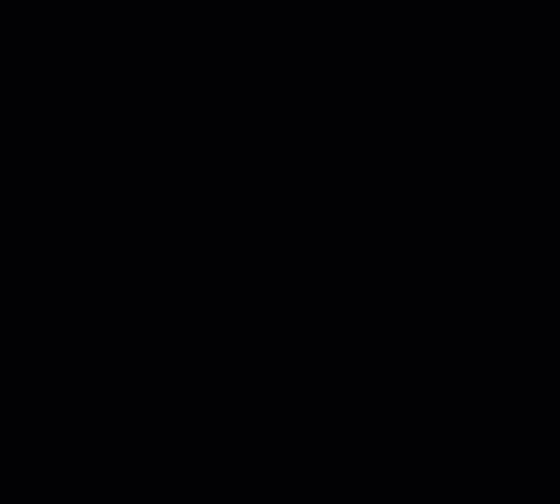

Right click on the data and select, "Export brushed" and name the variable "NewData". 

TransTime = double(NewData(:,1));
TransVelocity = double(NewData(:,2));
TransTime = TransTime - TransTime(1);  % time shift transient data to start at t=0

Plot subset of data which will be used for Curve Fit. 

figure('Name','Data Selected for Curve Fit');
plot(TransTime,TransVelocity,'k.','MarkerSize',0.5)
xlim([min(TransTime) max(TransTime) ])
ylim([min(TransVelocity)-10 max(TransVelocity)+10])
xlabel('Time (sec)');
ylabel('Rotor Velocity  \omega_r (rads/sec)');
grid on;

## Prepare of Curve Fitting

Get friction parameters to build custom equation for curve fitting.

dd = Simulink.data.dictionary.open('SGKitPlantData.sldd');
J0 = getValue(getEntry(getSection(dd,'Design Data'),'pmsmCoulombFrictionTorque'))
b = getValue(getEntry(getSection(dd,'Design Data'),'pmsmViscousFrictionCoefficient'))
discInertia = getValue(getEntry(getSection(dd,'Design Data'),'discInertia'))

Custom equation form for curve fit - general form

## 
$$\omega_r =\left(\omega_0 +\frac{\j_0 }{b}\right)\cdot e^{\left(-b\cdot \frac{t}{H}\right)} -\frac{J_0 }{b}$$


Build motor specific custom equation for curve fit

J0_Over_b = J0/b;
CustomEquation = ['(' num2str(TransVelocity(1)) ' + ',num2str(J0_Over_b),')*exp(-',num2str(b),'*x/H)-',num2str(J0_Over_b)];
disp(CustomEquation)

## Perform Curve Fit Interactively

Execute below code at MATLAB Command Prompt and copy the equation shown in the dialog box.

answer = inputdlg({'Custom Equation'},'Custom Equation',[1 40],{CustomEquation});

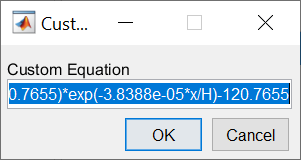

Open Curve Fitting Tool and Select TransTime and TransVelocity as X and Y data, respectively. 

Use the Custom Equation from above and select Custom Equation as the Fit Type. 

cftool

Save the Fitted Model to the Workspace (Fit > Save to Workspace)

Calculated H using curve fit

disp(['H = ' num2str(fittedmodel.H,'%.9f')]);

Update discInertia vale in Data Dictionary

setValue(getEntry(getSection(dd,'Design Data'),'discInertia'),fittedmodel.H);

## Compare Experiment Result with Desktop Simulation 

mdl = 'FieldOrientedController_MIL';
open_system(mdl);
switchConfig('MIL');
%switchMotorKit('SG_Inverter_RCP_Kit');

#### Select Signal Editor Experiement 

set_param([mdl,'/enManualTestInputs'],'Value','0'); % Select SignalEditor_Experiments as Test Inputs 
set_param([mdl,'/SignalEditor_Experiments'],'ActiveScenario',ExperimentType); % Select Experiment

#### View and Compare Data in Simulation Data Inspector

set_param(mdl,'SimulationCommand','start');
desktopRun = Simulink.sdi.Run.getLatest;
desktopRun.Name = ['Coastdown Sim - ' char(desktopRun.DateCreated)];
sigSim = getSignalsByName(desktopRun,'rotorVelocity');
Simulink.sdi.setSubPlotLayout(1,1);
sigSim.Checked = true; % Mark Signal for Plotting
Simulink.sdi.view; % Open Simulation Data Inspector

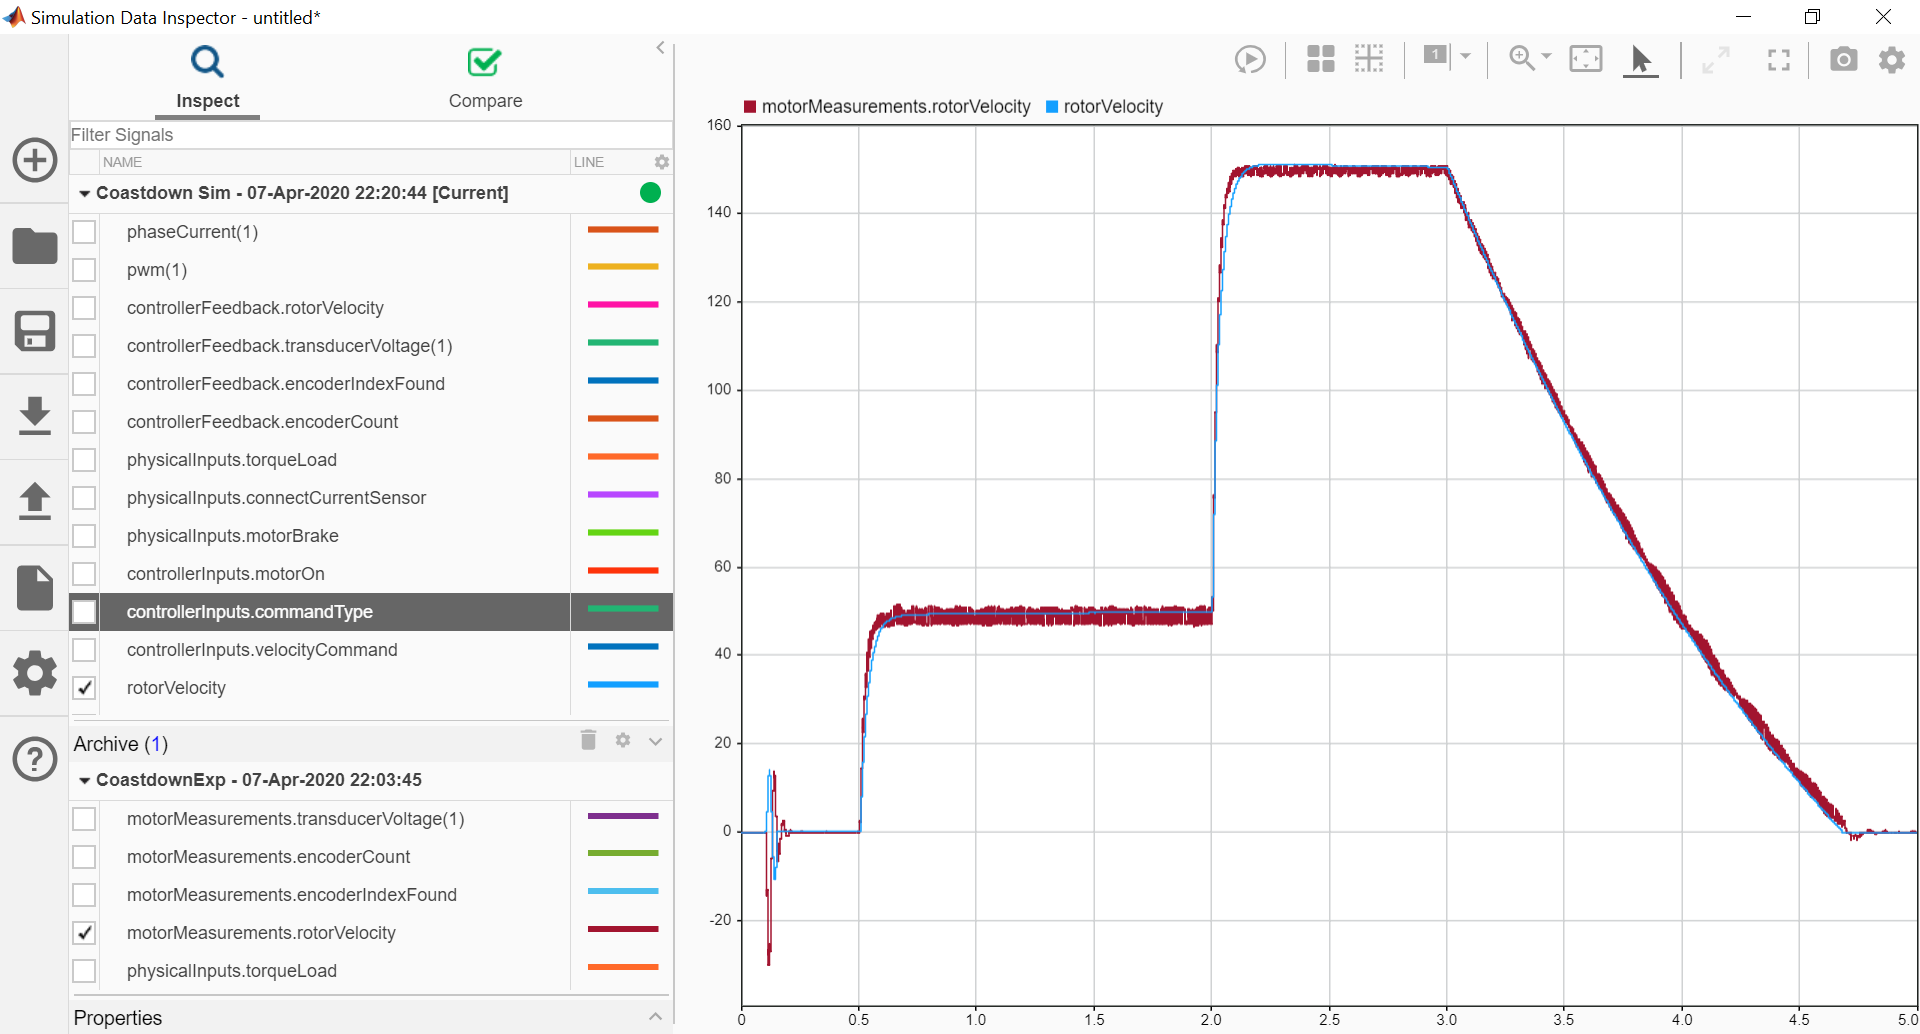

## Restore

% Clear up and Restore Data Dictionaries
dd.discardChanges;
clear mdl dd discInertia desktopRun sigExp sigSim answer CustomEquation b J0 J0_Over_b TransVelocity TransTime ...
    NewData fittedmodel experimentRun
